## Метод разложения в ряд Фурье

Круглый диэлектрический цилиндр, H-поляризаци

Метод разложения в ряд Фурье

05-04-21

close all;
clear variables;

### 1. Входные данные

%%  1 - входные данные  
% Параметры среды-1
e1 = 2.56;
mu1 = 1;
k1 = 2*pi*sqrt(mu1*e1);
eta1 = 120*pi*sqrt(mu1/e1); 

% Параметры среды-2
k2 = 2*pi;
eta2 = 120*pi;

% Параметры программы
a = 5/(2*pi);  % радиус круга 
N_harm = 100; % количество гармоник
N_circl = 600; % количество точек на круга 
phi_i_grad = 0; % угол падения [град]
phi_i_rad = 2*pi/360*phi_i_grad; % угол падения [рад]



### 2. Построение круга

dphi_grad = 360/N_circl; % угловой шаг на круга [град]
dphi_rad = 2*pi/N_circl; % угловой шаг на круга [рад]

% получение векторов углов и вектора ридиусов
phi_circl_rad = zeros(1, N_circl);
phi_circl_grad = zeros(1, N_circl);
a_for_graph = zeros(1, N_circl);
for i = 1 : N_circl    
    phi_circl_rad(i) = (i-1)*dphi_rad + dphi_rad/2;
    phi_circl_grad(i) = (i-1)*dphi_grad + dphi_grad/2;
    a_for_graph(i) = a;
end

### 3. Метод разложения ТОКОВ в ряд Фурье


% сохрнаим коэффициенты 
% j1_coef = zeros(1,N_circl);
% j2_coef = zeros(1,N_circl);
% Реальные токи 
I1 = zeros(1,N_circl);
I2 = zeros(1,N_circl);
% Поля
Es = zeros(1,N_circl);
Hs = zeros(1,N_circl);
Ep = zeros(1,N_circl);
Hp = zeros(1,N_circl);
% кол-во точек

for n_dot = 1 : N_circl   
    % текужщий угол
    cur_phi = phi_circl_rad(n_dot);
      
    % кол-во гармоник
    j1_sum = 0;
    j2_sum = 0;
    Es_sum = 0;
    Hs_sum = 0;
    Ep_sum = 0;
    Hp_sum = 0; 
    for n = -N_harm: 1 : N_harm

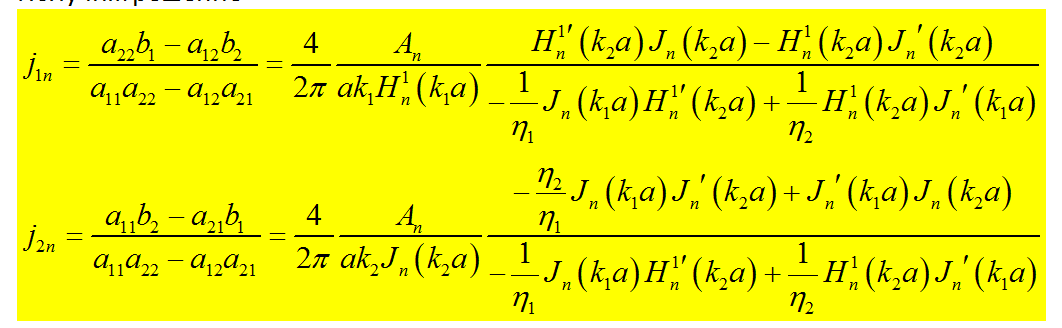

                
        An = (-1i)^n*exp(-1i*n*phi_i_rad);       
        Z = -1/eta1*besselj(n,k1*a)*dH(n,k2*a) + 1/eta2*besselh(n,1,k2*a)*dJ(n,k1*a);
        j1n = 4*An/(a*k1*besselh(n,1,k1*a)*2*pi) * (dH(n,k2*a)*besselj(n,k2*a) - besselh(n,1,k2*a)*dJ(n,k2*a))/Z;
        j2n = 4*An/(a*k2*besselj(n,k2*a)*2*pi) * (-eta2/eta1*besselj(n,k1*a)*dJ(n,k2*a) + dJ(n,k1*a)*besselj(n,k2*a))/Z;
        
        % суммарный ток при заданой угле на цилиндре
        j1_sum = j1_sum + j1n*exp(1i*n*cur_phi);
        j2_sum = j2_sum + j2n*exp(1i*n*cur_phi);

        % посчитаем поле на растоянии r = 2a
        ro = 2*a;

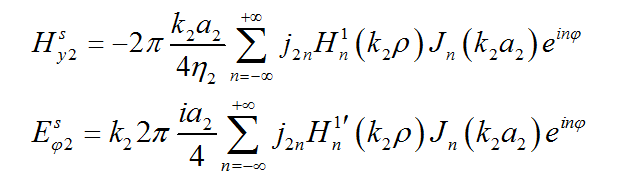

        % Рассеянное поле
        Es_sum = Es_sum - 2*pi*k2*ro/4/eta2*j2n*besselh(n,1,k2*ro)*besselj(n,k2*a)*exp(1i*n*cur_phi);
        Hs_sum = Hs_sum + k2*2*pi*1j*ro/4*j2n*dH(n,k2*ro)*besselj(n,k2*a)*exp(1i*n*cur_phi);
        

    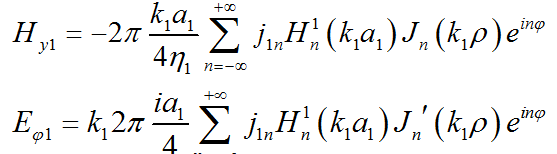

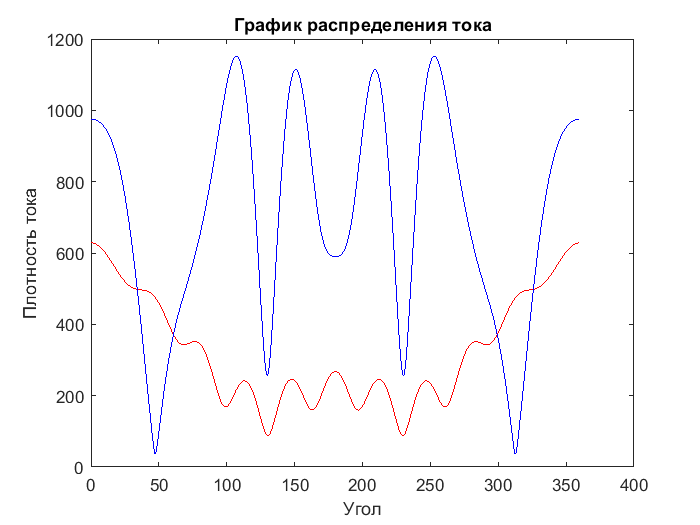

        % прошедшее поле
        Ep_sum = Ep_sum - 2*pi*k1*a/4/eta1*j1n*besselh(n,1,k1*a)*besselj(n,k1*ro)*exp(1i*n*cur_phi);
        Hp_sum = Hp_sum + k1*2*pi*1j*a/4*j1n*besselh(n,1,k1*a)*dJ(n,k1*ro)*exp(1i*n*cur_phi);
        
    end
    
    % сохранение тока от угла
    I1(n_dot) = j1_sum; 
    I2(n_dot) = j2_sum;
    
    % сохранение поля от угла
    Es(n_dot) = Es_sum;
    Hs(n_dot) = Hs_sum;
    Ep(n_dot) = Ep_sum;
    Hp(n_dot) = Hp_sum; 
end


% графики токов
plot(phi_circl_grad, abs(I1),'r',phi_circl_grad, abs(I2),'b')
title('График распределения тока'); 
xlabel('Угол'); 
% xlim([0,360])
ylabel('Плотность тока');

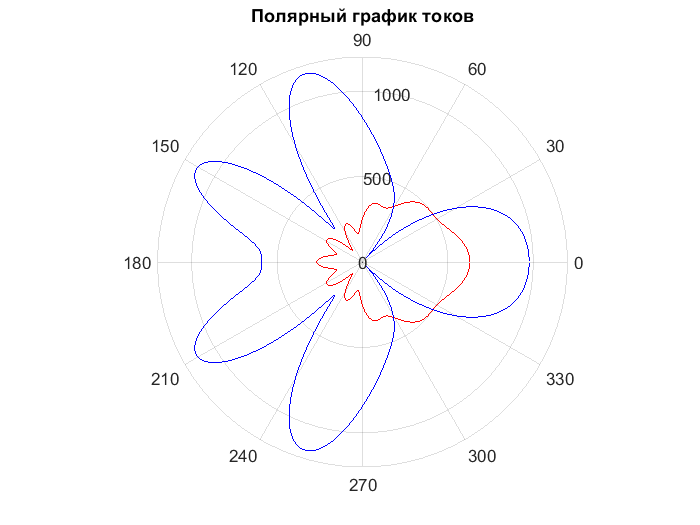


% палярный графики токов
polarplot(phi_circl_rad, abs(I1),'r',phi_circl_rad, abs(I2),'b')
title('Полярный график токов'); 


% % графики полей 
% plot(phi_circl_grad, abs(Es),'r',phi_circl_grad, abs(Ep),'b')
% title('E поле'); 
% xlabel('Угол'); 
% ylabel('');
% 
% % графики полей 
% plot(phi_circl_grad, abs(Hs),'r',phi_circl_grad, abs(Hp),'b')
% title('H поле'); 
% xlabel('Угол'); 
% ylabel('');

Полярные графики полей

% % графики полей 
% polarplot(phi_circl_rad, abs(Es),'r',phi_circl_rad, abs(Ep),'b')
% title('E поле'); 
% 
% 
% % графики полей 
% polarplot(phi_circl_rad, abs(Hs),'r',phi_circl_rad, abs(Hp),'b')
% title('H поле'); 

## ЭПР

RCS = zeros(721,1);
phi_rad_for_graf_DA = zeros(721,1);
phi_grad_for_graf_DA = zeros(721,1);

for p = 1 : 721
    Sum_H = 0;
    curr_phi_grad = (p-1)/2; % угол из формулы для приведения 721 к 360 градусам
    curr_phi_rad = 2*pi/360*curr_phi_grad;
    
    % запищем в массивы для дальнейшего использования
    phi_grad_for_graf_DA(p) = curr_phi_grad; % угол для графика
    phi_rad_for_graf_DA(p) = curr_phi_rad;
    
    for n = -N_harm : 1 : N_harm 
        An = ((-1i)^n)*exp(-1i*n*phi_i_rad);
        Z = -1/eta1*besselj(n,k1*a)*dH(n,k2*a) + 1/eta2*besselh(n,1,k2*a)*dJ(n,k1*a);
        j2n = 4*An/(a*k2*besselj(n,k2*a)*2*pi) * (-eta2/eta1*besselj(n,k1*a)*dJ(n,k2*a) + dJ(n,k1*a)*besselj(n,k2*a))/Z;

    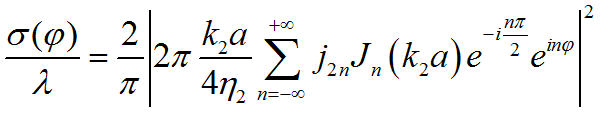 

        Sum_H = Sum_H + 2*pi*k2*a/4/eta2*j2n*besselj(n,k2*a)*exp(-1i*n*pi/2)*exp(1i*n*curr_phi_rad);      
    end
    
    RCS(p) = 10*log10((2/pi)*Sum_H*conj(Sum_H));

end



% график поля в дальней зоне от угла налюденя (не нормированный)
figure;
plot(phi_grad_for_graf_DA , RCS,'r-');

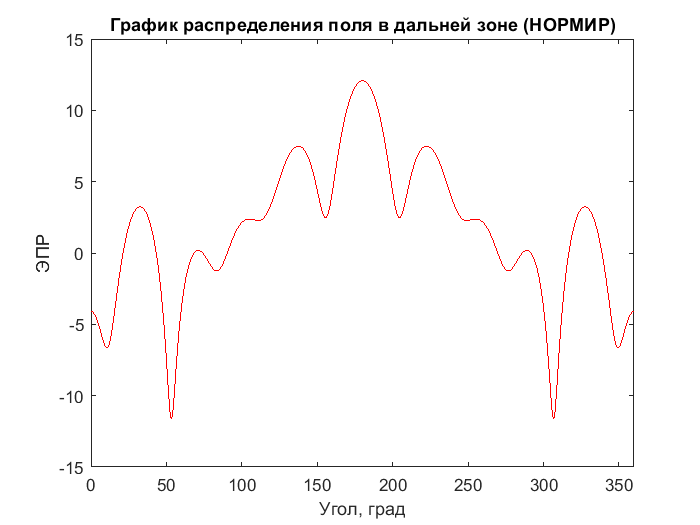

title('График распределения поля в дальней зоне (НОРМИР)'); 
xlim([0 360])
xlabel('Угол, град'); 
ylabel('ЭПР');


% % график поля в дальней зоне от угла налюденя (нормированный)
% normir = k2*eta2/4;
% figure;
% plot(phi_grad_for_graf_DA , RCS/normir*1000,'r-');
% title('График распределения поля в дальней зоне (НОРМИР)'); 
% xlim([0 360])
% xlabel('Угол, град'); 
% ylabel('ЭПР');
% 
% 
% figure;
% polarplot(phi_rad_for_graf_DA, RCS,'r-');

### Вывод данных для графиков

% name_file = strcat('I_FURIE_circl_diel_Hpol_j1_', num2str(N_circl),'.dat');
% f01 = fopen(name_file,'w');
% 
% % за максимум Y примем значения в центре передней стороны падения
% 
% for n=1:N_circl
%     fprintf(f01,' %10.5f %10.5f\n', phi_circl_grad(n), abs(I1(n)));
% end
% 
% fclose(f01);

% name_file = strcat('I_FURIE_circl_diel_Hpol_j2_', num2str(N_circl),'.dat');
% 
% f02 = fopen(name_file,'w');
% 
% % за максимум Y примем значения в центре передней стороны падения
% 
% for n=1:N_circl
%     fprintf(f02,' %10.5f %10.5f\n', phi_circl_grad(n), abs(I2(n)));
% end
% 
% fclose(f02);

% name_file = strcat('DA_FURIE_circl_diel_Hpol_j2_', num2str(N_circl),'.dat');
% f03 = fopen(name_file,'w');
% 
% % за максимум Y примем значения в центре передней стороны падения
% 
% for n= 1 : 721
%     fprintf(f03,' %10.5f %10.5f\n', phi_grad_for_graf_DA(n), RCS(n));
% end
% 
% fclose(f03); 

### Используемые функции

function [dJ_calc] = dJ(n,x)
    dJ_calc = n/x*besselj(n,x) - besselj(n+1,x);
end
function [dH_calc] = dH(n,x)
    dH_calc = n/x*besselh(n,1,x) - besselh(n+1,1,x);
end